# Chapter X

## Hydraulics

Load library paths

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


format shortg

**Basic concepts**

% Velocity
Q = 10; % Flow (m3/h)
D = 100; % Diameter (cm)
Dm = D/100; % Diameter in m
V = 4*Q / (pi*Dm^2) % Velocity (m/h)

V =        12.732


## Reynolds Numbers

rho = 1000; % kg/m^3
D = 0.1; % m
mu = 1.0016e-3; % kg/(m.s)
v = 0.2; % m/s
Re = rho * D * v/mu

Re =         19968


Basic laws

**The mass conservation law states that mass can be neither created nor destroyed, i.e. any mass entering a system must either accumulate in it or leave it.**

**Energy conservation law: Water in a pipe system may possess three forms of internal energy: potential, pressure and kinetic**

- **Potential is due to the position of the fluid wrt some reference. Two points have different potential energy due to differences in elevation**

- **Pressure energy is due the hydrostatic pressure (the internal energy of a fluid due to the pressure exerted on the pipe)**

- **Kinetic energy is is the energy possessed by a liquid of weight W moving at a velocity v**

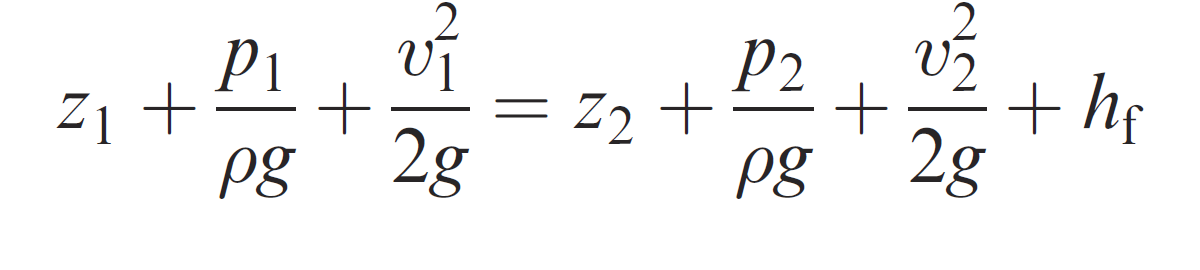

In the exaple, we consider a simple network of a pipe with 3 nodes. The pipe is galvanized iron (roughness coeff 0.15 in DW) and also has a short-radius elbow with 0.9 minor loss coefficient

clear
G = epanet('singlepipeHW.inp')

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeHW.inp"...
Input File "singlepipeHW.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1
                      DemandModelPexp: 0.5
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
                            InputFile: 'C:\Users\eldemet\Documents\G

z = G.getNodeElevations

z =     80    50    40   100


g = 9.80665; % standard gravitational acceleration m^2/s 
rho = 1000; % kg/m^3 density of water in 4 degrees C
H = G.getComputedHydraulicTimeSeries('Pressure','Velocity',...
    'Head');
m2Pa = 9806.65;
p = m2Pa * H.Pressure; % pressure in Pascals
v = [H.Velocity 0]; % velocity in m/s. In the reservoir there is zero velocity

h = z + p/(rho*g) + v.^2/(2*g)

h =        99.431       93.721        93.15          100


hepanet = H.Head

hepanet =        99.429       93.719       93.148          100



h(4)-h(1)

ans =       0.56938


h(1)-h(2)

ans =        5.7097


h(2)-h(3)

ans =       0.57098


figure
%% Get data from Net1 benchmark
%g = epanet('singlepipeHW.inp');
Nnode = G.getNodeCount

Nnode = int32
   4


A = zeros(Nnode);
C = G.getNodeCoordinates;
L = G.getLinkLength;
D = G.getLinkDiameter;
E = G.getNodeElevations;
NIP = G.getNodeNameID

NIP = 1×4 cell array
    {'2'}    {'3'}    {'4'}    {'1'}


EIP = G.getLinkNameID

EIP = 1×3 cell array
    {'1'}    {'2'}    {'3'}


Elev = G.getNodeElevations

Elev =     80    50    40   100



%Compute the mean flow
H = G.getComputedHydraulicTimeSeries;
Fmean = mean(H.Flow,1);
Vel = H.Velocity

Vel =       0.17684      0.17684      0.17684


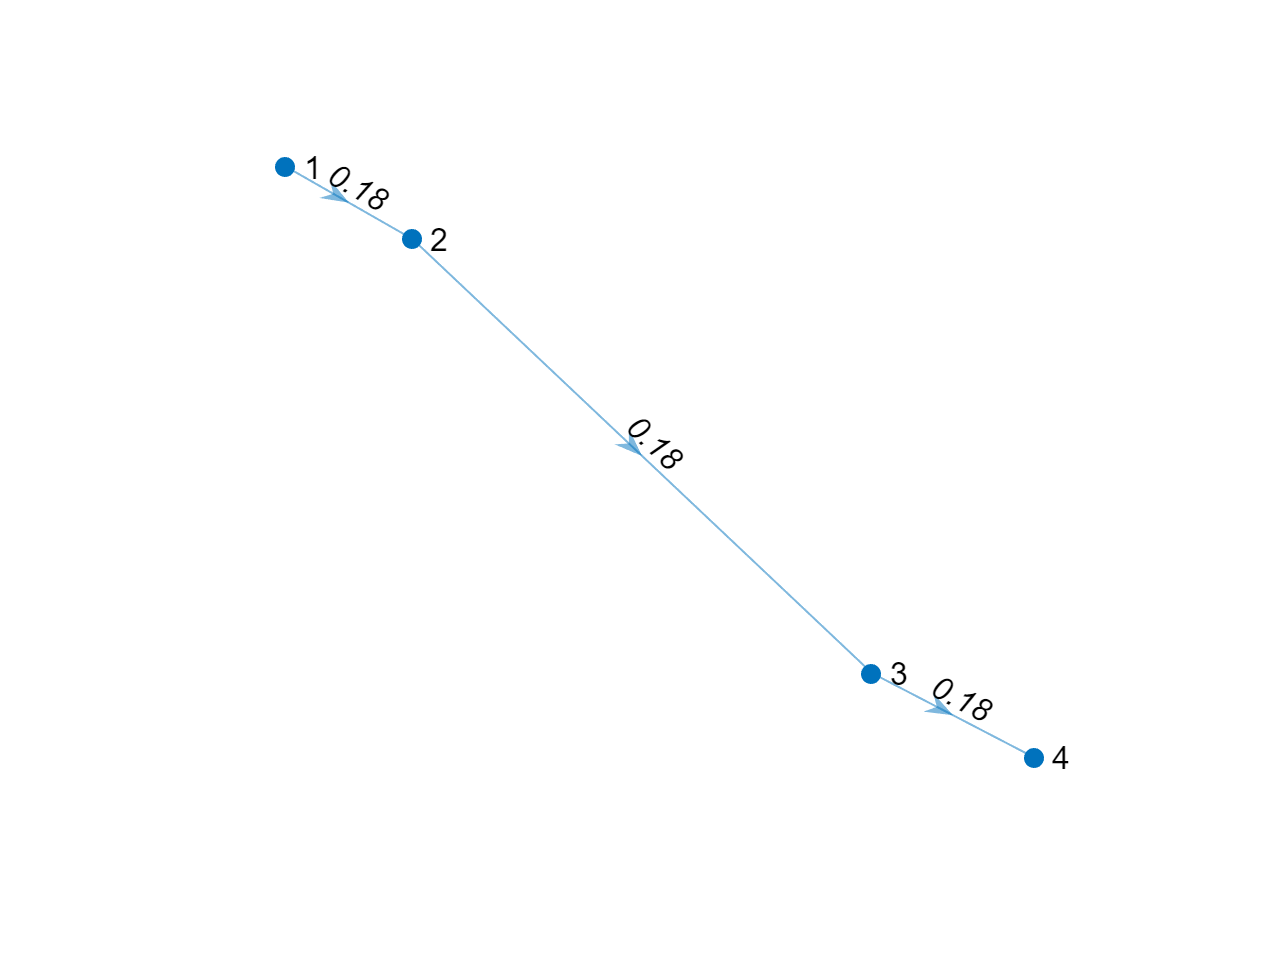


%% Compute the new adjacency matrix based on the mean flow in the network
Fsign = sign(Fmean);
Nidx = G.getLinkNodesIndex;
for i = 1:size(Nidx,1)
    if Fsign(i) == 1
        A(Nidx(i,1),Nidx(i,2)) = 1;
    else 
        A(Nidx(i,2),Nidx(i,1)) = 1;
    end
end

G2 = digraph(A);
G2.Nodes.Name = NIP';
G2.Edges.Name = EIP';
%G2.Edges.Weight = abs(Vp'./Fmean'); % compute time delay in each pipe

p = plot(G2,'XData',C{1},'YData',C{2},'EdgeLabel', round(Vel,2), 'NodeLabel', NIP);
%p = plot(G2,'XData',C{1},'YData',C{2},'EdgeLabel',round(G2.Edges.Weight,1));
set(gca,'visible','off')

% clear h
% G = epanet('singlepipeHW.inp')
% G.plot
% H = G.getComputedHydraulicTimeSeries('Pressure','Velocity')
% z = G.getNodeElevations
% lm = G.getLinkMinorLossCoeff;
% d = G.getLinkDiameter;
% H.Pressure
% p = 9806.65 * H.Pressure % Pressure from mWC to Pascals
% v = H.Velocity % m/s
% rho = 1000; % kg/m^3 density of water in 4 degress C as in epanet
% g = 9.80665; % standard gravitational acceleration m^2/s 
% 
% Q = H.Flow;
% L = G.getLinkLength;
% 
% h = z + p/(rho*g) + v(1)^2/(2*g)
% 
% % h(1) = z(1) + p(1)/(rho*g) + v(1)^2/(2*g) + lm(1)*v(1)^2/(d(1)*2*g);
% % h(2) = z(2) + p(2)/(rho*g) + v(2)^2/(2*g) + lm(2)*v(2)^2/(d(2)*2*g);
% % h(3) = z(3) + p(3)/(rho*g) + v(3)^2/(2*g) + lm(3)*v(3)^2/(d(3)*2*g);
% % h(4) = z(4) + p(4)/(rho*g) + 0;
% % h
% hepa = H.Head
% 
% % Computed headloss
% dh12 = h(1) - h(2)
% dhepa12 = hepa(1) - hepa(2) 

**Friction lossess equation using HW**

% Hazen Williams
clear
G = epanet('singlepipeHW.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeHW.inp"...
Input File "singlepipeHW.inp" loaded sucessfuly.


H = G.getComputedHydraulicTimeSeries('Flow','Head'); % compute flow and head
h = H.Head; % computed head
Q = H.Flow; % computed flows
L = G.getLinkLength; % in m
C = G.getLinkRoughnessCoeff; % unitless, for galvanized iron
D = G.getLinkDiameter; % diameter in mm
Dm = D/1000; % diameter in meters
Qcms = Q/3600; % m3/second

We compute the EPANET results for comparison

Dhfepanet = [h(4)-h(1), h(1)-h(2), h(2)-h(3)]

Dhfepanet =       0.57098       5.7097      0.57098


Compute for CMS

beta = 1.852;
alphaCMS = 10.67 * L./(C.^1.852 .* Dm.^4.8704)

alphaCMS =    1.1167e+05   1.1167e+06   1.1167e+05


Dhf1 =  alphaCMS .* Qcms.^beta

Dhf1 =       0.57035       5.7035      0.57035


Compute for CMH

coeff = 3600^-1.852;
alphaCMH = 10.67 *coeff * L./(C.^1.852 .* Dm.^4.8704)

alphaCMH =       0.02895       0.2895      0.02895


%alphaCMH = coeff * 1000^4.8704 * L./(C.^1.852 .* D.^4.8704)

Dhf2 =  alphaCMH .* Q.^beta

Dhf2 =       0.57035       5.7035      0.57035


create matrix

D = [Dhfepanet; Dhf1; Dhf2]

D =       0.57098       5.7097      0.57098
      0.57035       5.7035      0.57035
      0.57035       5.7035      0.57035


**Computing headling using Darcy Weisbach**

% Compute pipe flow resistance coefficient for Darcy Weisbach
clear
G = epanet('singlepipeDW.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeDW.inp"...
Input File "singlepipeDW.inp" loaded sucessfuly.


H = G.getComputedHydraulicTimeSeries('Flow','Velocity','Head'); % compute flow, velocity and head
h = H.Head; % computed head in m
Q = H.Flow; % computed flow in m^3/h
L = G.getLinkLength; % pipe length in m
k = G.getLinkRoughnessCoeff; % mm for galvanized iron
D = G.getLinkDiameter; % diameters in mm
V = H.Velocity % velocity in m/s

V =       0.17684      0.17684      0.17684



% Adjust the units
km = k/1000; % roughness in meters
Dm = D/1000; % diameter in meters
Qcms = Q/3600 % flow in m^3/s

Qcms =     0.0013889    0.0013889    0.0013889



% We compute the headloss using the EPANET computations
Dhfepanet = [h(4)-h(1), h(1)-h(2), h(2)-h(3)];

We load some fundamental variables

rho = 1000; % kg/m^3 density of water
g = 9.80665; % standard gravitational acceleration m^2/s 
mu = 1.0016e-3; % viscosity in kg/(ms) or Pa.s

Compute the Reynolds number

Re = rho .* V .* Dm / mu;

Compute the friction coefficient

lambda = 0.25./(log10((km./Dm)/3.71 + 5.74./Re.^0.9)).^2;

alphaCMS = 8/pi^2/g .* lambda .* L./Dm.^5;
Dhf1 =  alphaCMS .* Qcms.^2;

correction for flow

corr = 3600^-2; % correction for CMH and D in m 

alphaCMH = corr * 8/pi^2/g .* lambda .* L./Dm.^5;

Dhf2 =  alphaCMH .* Q.^2;

create matrx

D = [Dhfepanet; Dhf1; Dhf2]

D =       0.47658       4.7658      0.47658
      0.47507       4.7507      0.47507
      0.47507       4.7507      0.47507


Compute friction for various Re

**omputing headling using Darcy Weisbach**

% Compute pipe flow resistance coefficient for Darcy Weisbach
clear
figure
G = epanet('singlepipeDW.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeDW.inp"...
Input File "singlepipeDW.inp" loaded sucessfuly.


L = G.getLinkLength; % pipe length in m
D = G.getLinkDiameter; % diameters in mm
Dm = D/1000; % diameter in meters

% Parameters for interopolation
ab = 0.00328895476345399058690;
aa = -1.5634601348517065795;

rangeED = 0.0000:0.005:0.05 % range of coefficients (in mm)

rangeED =             0        0.005         0.01        0.015         0.02        0.025         0.03        0.035         0.04        0.045         0.05


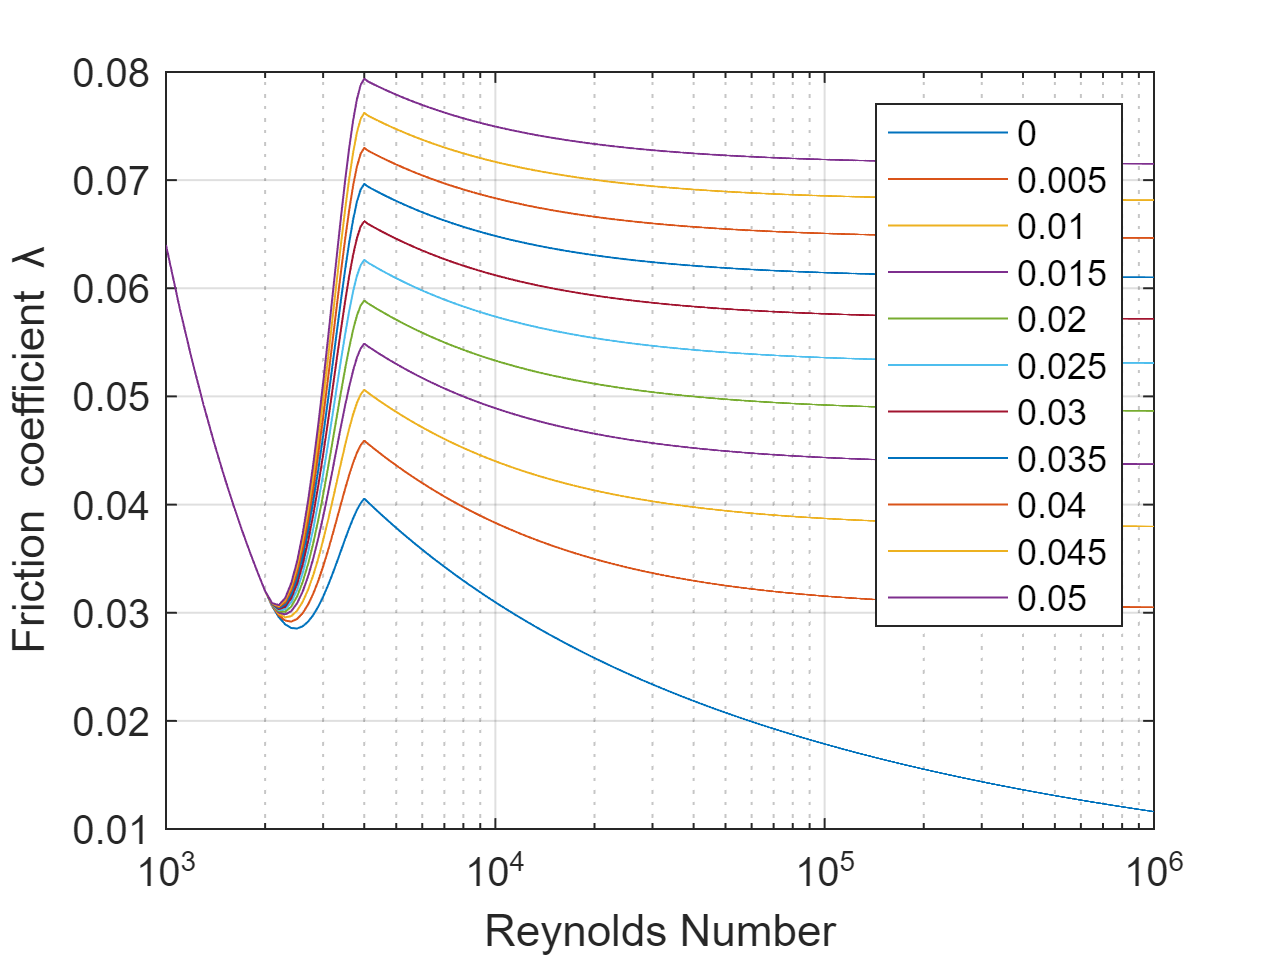

for ED = rangeED
    rangeRe = 1000:100:1000000; % range of Reynolds numbers
    lambda = [0 0 0]; % initialize lambda
    lambda2 = [0 0 0];
    cnter = 1; % counter
    for Re = rangeRe
        if Re<2000
            lambda(cnter,:) = [64/Re 64/Re 64/Re];
        end
        if Re>=2000 && Re<= 4000
            r = Re/2000;
            y2 = ED./(3.7) + ab;
            y3 = -2.*log10(y2);
            fa = (y3).^-2;
            fb = fa.*(2- (aa.*ab./(y2.*y3)));
            x1 = 7.*fa-fb;
            x2 = 0.128 - 17.*fa + 2.5.*fb;
            x3 = -0.128 + 13.*fa -2.*fb;
            x4 = 0.032 - 3.*fa + 0.5.*fb;
            lambda(cnter,:) = x1 + r.*(x2+ r.*(x3 + r.*x4));
        end
        if Re>4000
            lambda(cnter,:) = 0.25./(log10((ED)/3.71 + 5.74./Re.^0.9)).^2;
        end
        %lambda2(cnter,:) = 1./(-2.*log10(ED./3.7065 - 5.0452./Re.*log10((ED.^1.1098./2.8257+(7.149./Re)^0.8981)))).^2;
        cnter = cnter+1;
    end
    semilogx(rangeRe, lambda(:,2))
    hold on
    %semilogx(rangeRe, lambda2(:,2))
end
grid on
xlabel('Reynolds Number')
ylabel('Friction coefficient \lambda')
legend(string(rangeED))


% f1 = 0.0055 .* ( 1 + (2 .* 10^4 .* km./Dm + 10^6./Re).^(1/3))
% f2 = 1./(1.8*log10(6.9./Re+(km./(3.71.*Dm)).^1.11)).^2 
% f3 = 0.25./(log10((km./Dm)/3.71 + 5.74./Re.^0.9)).^2
% 
% m2Pa = 9806.65;
% Dhf1 = rho .* f3 .* V.^2 .* L./(2*Dm)/m2Pa
% 
% alphaCMS = 8/pi^2/g .* f3 .* L./Dm.^5;
% Dhf2 =  alphaCMS .* Qcms.^2
% 
% h(4)-h(1)
% h(1)-h(2)
% h(2)-h(3)
% 
% corr1 = 3600^-2; % correction for CMH and D in m 
% alphaCMH = corr1 * 8/pi^2/g .* f3 .* L./Dm.^5;
% Dhf3 =  alphaCMH .* Q.^2

Interpolation 

Re = 3000;




**Minor losses**

**EPANET models it as kQ^2, a more detailed description is provided in **

[**https://swmm5.org/2017/11/07/innovyze-h2ocalc-head-loss-due-to-transitions-and-fittings-local-loss/**](https://swmm5.org/2017/11/07/innovyze-h2ocalc-head-loss-due-to-transitions-and-fittings-local-loss/)** and the ***Nicklow and Boulos (2005) book *

% Hazen Williams
clear
G = epanet('singlepipeHWminor.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeHWminor.inp"...
Input File "singlepipeHWminor.inp" loaded sucessfuly.


H = G.getComputedHydraulicTimeSeries('Flow','Head','Velocity'); % compute flow and head
lm = G.getLinkMinorLossCoeff

lm =      0     2     0


h = H.Head; % computed head
Q = H.Flow; % computed flows
V = H.Velocity;
L = G.getLinkLength; % in m
C = G.getLinkRoughnessCoeff; % unitless, for galvanized iron
D = G.getLinkDiameter; % diameter in mm
Dm = D/1000; % diameter in meters
Qcms = Q/3600; % m3/second
g = 9.80665; % standard gravitational acceleration m^2/s 


We compute the EPANET results for comparison

Dhfepanet = [h(4)-h(1), h(1)-h(2), h(2)-h(3)]

Dhfepanet =       0.57098       5.7129      0.57097


Compute for CMH

beta = 1.852;
coeff = 3600^-1.852;
alphaCMH = 10.67 *coeff * L./(C.^1.852 .* Dm.^4.8704)

alphaCMH =       0.02895       0.2895      0.02895


Dhf =  alphaCMH .* Q.^beta;


Dhl = lm .* V.^2/(2*g);

coeff = 3600^-2;
Kappa = lm .* 8 ./(g * pi^2 .* Dm.^4) * coeff;
Dhl2 = Kappa.* Q.^2 

Dhl2 =             0    0.0031889            0




Dh = Dhf + Dhl

Dh =       0.57035       5.7067      0.57035


create matrix

D = [Dhfepanet; Dh]

D =       0.57098       5.7129      0.57097
      0.57035       5.7067      0.57035


**Pumps**

dpQ = 2.2;
dpH = 26.5;
x = [dpQ; 0 ; dpQ*2];
y = [dpH; 4/3*dpH; 0];
%p = polyfit(x,y,2)

%p2 = fit(x,y,'power2')

p = [x.^2 ones(3,1)]\y

p =    -1.8251
   35.3333



q = linspace(0,dpQ*2);
f = p(2) + p(1).*q.^2

f =    35.3333   35.3297   35.3189   35.3009   35.2757   35.2432   35.2036   35.1567   35.1026   35.0413   34.9728   34.8971   34.8142   34.7241   34.6267   34.5222   34.4104   34.2915   34.1653   34.0319   33.8913   33.7435   33.5885   33.4262   33.2568   33.0802   32.8963   32.7052   32.5070   32.3015   32.0888   31.8689   31.6417   31.4074   31.1659   30.9171   30.6612   30.3980   30.1276   29.8500   29.5652   29.2732   28.9740   28.6676   28.3539   28.0331   27.7050   27.3697   27.0272   26.6775


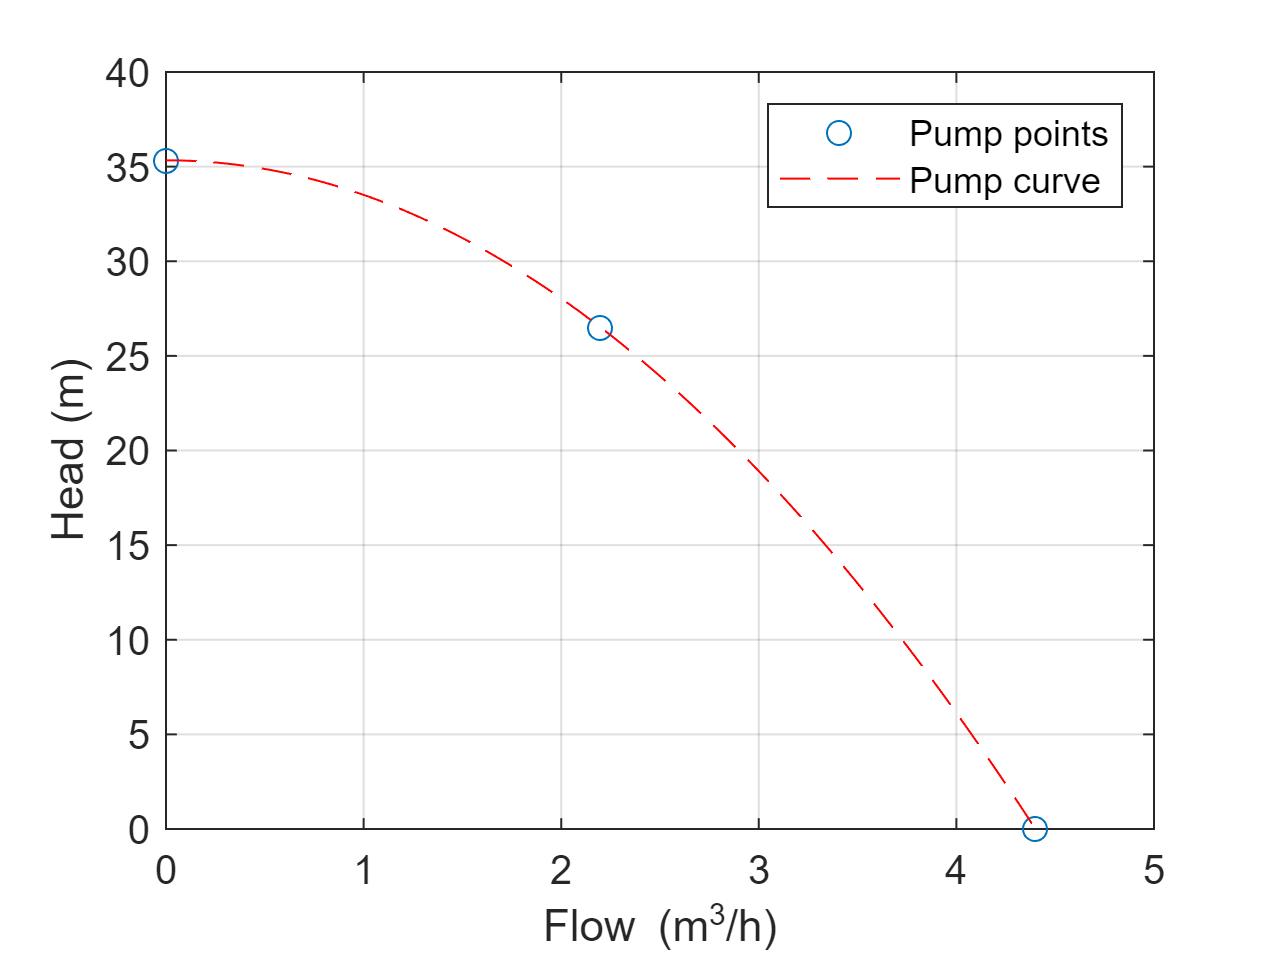

%f2 = polyval(p2,q)

figure
plot(x,y,'o')
hold on
plot(q,f,'r--')
%plot(q,f2,'r--')
legend('Pump points','Pump curve')
grid on
xlabel('Flow (m^3/h)')
ylabel('Head (m)')

Compute solutions for networks of pipes

**Todini-Pilati Method**

**Create system of equations**

$H_i - H_j = R Q_{ij}^n+KQ_{ij}^2$ for all pipes


$$\sum_{j=1}^{n_p} Q_{ij} = q_i$$


clear 
%G = epanet('Net8.inp');
G = epanet('singlepipeHW.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeHW.inp"...
Input File "singlepipeHW.inp" loaded sucessfuly.


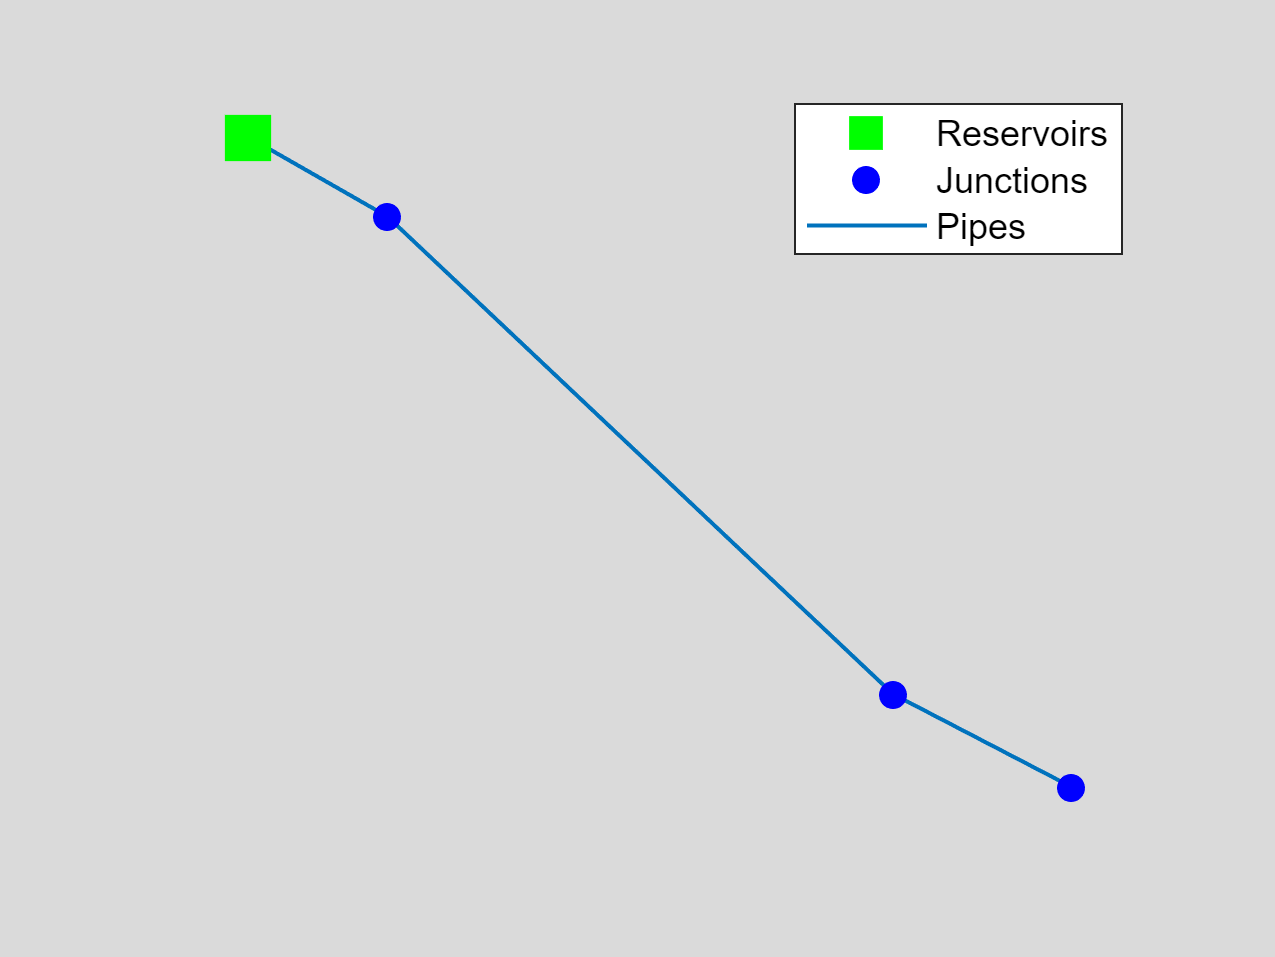

ans =   Axes with properties:

             XLim: [-2066 8198.1]
             YLim: [3937.1 7635.2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


G.plot

% Compute for comparison
H = G.getComputedHydraulicTimeSeries;

C = G.LinkRoughnessCoeff'; %unitless
D = G.LinkDiameter';
Dm = D/1000; %Diameter in m
L= G.LinkLength'; % Length in meters

% Compute HW coefficients for m^3/h
n = 1.852;
%K = 10.67 * L./(C.^1.852 .* Dm.^4.8704)/(1000^4.8704/3600^1.852)
K = 1.1088*10^11*(C.^(-n)).*(D.^-4.867).*(L/100)

K =      0.028854
      0.28854
     0.028854


K(G.LinkPumpIndex)=-1; %Identify pumps

% Demands from each node junction
tmp = count(G.getNodeType, 'JUNCTION');
qext = G.getNodeActualDemand(find(tmp==1))'

qext =      0
     0
     5



tmp = count(G.getNodeType, 'RESERVOIR');
E = G.getNodeElevations';
E(find(tmp == 0)) = 0

E =      0
     0
     0
   100


compute matrices

node_node_link_index = double([G.NodesConnectingLinksIndex G.LinkIndex']);
A21 = zeros(G.NodeJunctionCount,G.LinkCount); %size nodes x pipes
for i=1:length(G.NodesConnectingLinksIndex)
    if  ~ismember(node_node_link_index(i,1),G.NodeReservoirIndex) && ...
        ~ismember(node_node_link_index(i,1),G.NodeTankIndex)&& ...
        G.getLinkInitialStatus(node_node_link_index(i,3))==1
    A21(node_node_link_index(i,1),node_node_link_index(i,3))=-1;
    end
    if ~ismember(node_node_link_index(i,2),G.NodeReservoirIndex) && ...
       ~ismember(node_node_link_index(i,2),G.NodeTankIndex)&& ...
       G.getLinkInitialStatus(node_node_link_index(i,3))==1
    A21(node_node_link_index(i,2),node_node_link_index(i,3))=1;
    end
end
A21

A21 =      1    -1     0
     0     1    -1
     0     0     1


A12 = A21'

A12 =      1     0     0
    -1     1     0
     0    -1     1


compute 

A10 = zeros(G.LinkCount,G.NodeCount);
index=[];
for i=1:length(G.NodeReservoirIndex)
    index=find(node_node_link_index(:,1)==G.NodeReservoirIndex(i));
    A10(index,G.NodeReservoirIndex(i))=-1;
    index=find(node_node_link_index(:,2)==G.NodeReservoirIndex(i));
    A10(index,G.NodeReservoirIndex(i))=1;
end
for i=1:length(G.NodeTankIndex)
    index=find(node_node_link_index(:,1)==G.NodeTankIndex(i));
    A10(index,G.NodeTankIndex(i))=-1;
    index=find(node_node_link_index(:,2)==G.NodeTankIndex(i));
    A10(index,G.NodeTankIndex(i))=1;
end
%Known heads of reservoirs and tanks
h0 = E;% tank head
hext = A10*h0

hext =   -100
     0
     0


solve using the Todini algorithm

%% Solve Hydraulics with Todini and Pilati method
% Initialize Newton iteration 
Qinit = 1*ones(G.LinkCount,1);
hinit = G.NodeElevations';
hinit(G.NodeReservoirIndex) = [];
Q = Qinit; h = hinit;
np = G.LinkCount;
nu = G.NodeJunctionCount;
itnum = 20; %number of iterations

% Newton iterations
for iter=1:itnum
    %A11 matrix - Hazen-Williams
    A11=diag(K.*(abs(Q).^(n-1)));
    A11Q=A11*Q;
    for i = 1:G.getLinkPumpCount
        Qp=Q(G.LinkPumpIndex(i));
        if Qp>=0
            A11Q(G.LinkPumpIndex(i))=-(Acoef(i) - Bcoef(i)*Qp^Ccoef(i));
        else
            A11Q(G.LinkPumpIndex(i))=-(Acoef(i) + Bcoef(i)*abs(Qp)^Ccoef(i));
        end
%         A11Q(G.LinkPumpIndex(i))=-(Acoef(i)*Qp^2 + Bcoef(i)*Qp + Ccoef(i));
%         A11Q(G.LinkPumpIndex(i))=-(Acoef(i)*Qp^2 + Ccoef(i));
    end    
    %Cost function Dz
    Dz = double([A11Q  + A12*h + hext;  
                 A21*Q         - qext]); 
             
    %Cost function derivative J
    N=diag(n*ones(size(A11(:,1))));
    NA11=N*A11;
    for i = 1:G.getLinkPumpCount
        Qp=Q(G.LinkPumpIndex(i));
        NA11(G.LinkPumpIndex,G.LinkPumpIndex)=-(-Bcoef(i)*Ccoef(i)*abs(Qp)^(Ccoef(i)-1));
    end
    J = [NA11    A12;
          A21   zeros(G.NodeJunctionCount)];   
       
    %Update
    options=optimset('Display', 'off');
    Dx = linprog(ones(1,size(J,1)),[],[],double(J),double(Dz),[],[],[],options);
    DQ = -Dx(1:np); 
    Dh = -Dx(np+1 : np+nu);   
    Q = Q + DQ;
    h = h + Dh;
end

% for closed valve pipes, flow bounds are exactly zero
Q(find(abs(Q)<0.00001))=0;

Q

Q =      5
     5
     5


h

h =        99.432
       93.747
       93.178


clear
G = epanet('singlepipeDW.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "singlepipeDW.inp"...
Input File "singlepipeDW.inp" loaded sucessfuly.


ans =   Axes with properties:

             XLim: [-2066 8198.1]
             YLim: [3937.1 7635.2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


G.plot

% Compute for comparison
H = G.getComputedHydraulicTimeSeries;

C = G.LinkRoughnessCoeff'; %unitless
D = G.LinkDiameter';
Dm = D/1000; %Diameter in m
L= G.LinkLength'; % Length in meters

% Compute HW coefficients for m^3/h
%n = 1.852;
%K = 10.67 * L./(C.^1.852 .* Dm.^4.8704)/(1000^4.8704/3600^1.852)
%K = 1.1088*10^11*(C.^(-n)).*(D.^-4.867).*(L/100)
%K(G.LinkPumpIndex)=-1; %Identify pumps

n=2;
%C=double(d.LinkRoughnessCoeff'); %unitless
%D=double(d.LinkDiameter')/1000; %Diameter in meters
%L=double(d.LinkLength'); % Length in meters
g=9.8*(12960000); %meters per hour squared
%K = 1.3086*(8*L.*C*(1/60)) ./ (g*pi^2*Dm.^5); %Darcy-Weisbach in SI
K =        (8*L.*C)        ./ (g*pi^2*Dm.^5); %Darcy-Weisbach in SI

% Demands from each node junction
tmp = count(G.getNodeType, 'JUNCTION');
qext = G.getNodeActualDemand(find(tmp==1))'

qext =      0
     0
     5



tmp = count(G.getNodeType, 'RESERVOIR');
E = G.getNodeElevations';
E(find(tmp == 0)) = 0

E =      0
     0
     0
   100


compute matrices

node_node_link_index = double([G.NodesConnectingLinksIndex G.LinkIndex']);
A21 = zeros(G.NodeJunctionCount,G.LinkCount); %size nodes x pipes
for i=1:length(G.NodesConnectingLinksIndex)
    if  ~ismember(node_node_link_index(i,1),G.NodeReservoirIndex) && ...
        ~ismember(node_node_link_index(i,1),G.NodeTankIndex)&& ...
        G.getLinkInitialStatus(node_node_link_index(i,3))==1
    A21(node_node_link_index(i,1),node_node_link_index(i,3))=-1;
    end
    if ~ismember(node_node_link_index(i,2),G.NodeReservoirIndex) && ...
       ~ismember(node_node_link_index(i,2),G.NodeTankIndex)&& ...
       G.getLinkInitialStatus(node_node_link_index(i,3))==1
    A21(node_node_link_index(i,2),node_node_link_index(i,3))=1;
    end
end
A21

A21 =      1    -1     0
     0     1    -1
     0     0     1


A12 = A21'

A12 =      1     0     0
    -1     1     0
     0    -1     1


compute 

A10 = zeros(G.LinkCount,G.NodeCount);
index=[];
for i=1:length(G.NodeReservoirIndex)
    index=find(node_node_link_index(:,1)==G.NodeReservoirIndex(i));
    A10(index,G.NodeReservoirIndex(i))=-1;
    index=find(node_node_link_index(:,2)==G.NodeReservoirIndex(i));
    A10(index,G.NodeReservoirIndex(i))=1;
end
for i=1:length(G.NodeTankIndex)
    index=find(node_node_link_index(:,1)==G.NodeTankIndex(i));
    A10(index,G.NodeTankIndex(i))=-1;
    index=find(node_node_link_index(:,2)==G.NodeTankIndex(i));
    A10(index,G.NodeTankIndex(i))=1;
end
%Known heads of reservoirs and tanks
h0 = E;% tank head
hext = A10*h0

hext =   -100
     0
     0


solve using the Todini algorithm

%% Solve Hydraulics with Todini and Pilati method
% Initialize Newton iteration 
Qinit = 1*ones(G.LinkCount,1);
hinit = G.NodeElevations';
hinit(G.NodeReservoirIndex) = [];
Q = Qinit; h = hinit;
np = G.LinkCount;
nu = G.NodeJunctionCount;
itnum = 20; %number of iterations

% Newton iterations
for iter=1:itnum
    %A11 matrix - Hazen-Williams
    A11=diag(K.*(abs(Q).^(n-1)));
    A11Q=A11*Q;
    for i = 1:G.getLinkPumpCount
        Qp=Q(G.LinkPumpIndex(i));
        if Qp>=0
            A11Q(G.LinkPumpIndex(i))=-(Acoef(i) - Bcoef(i)*Qp^Ccoef(i));
        else
            A11Q(G.LinkPumpIndex(i))=-(Acoef(i) + Bcoef(i)*abs(Qp)^Ccoef(i));
        end
%         A11Q(G.LinkPumpIndex(i))=-(Acoef(i)*Qp^2 + Bcoef(i)*Qp + Ccoef(i));
%         A11Q(G.LinkPumpIndex(i))=-(Acoef(i)*Qp^2 + Ccoef(i));
    end    
    %Cost function Dz
    Dz = double([A11Q  + A12*h + hext;  
                 A21*Q         - qext]); 
             
    %Cost function derivative J
    N=diag(n*ones(size(A11(:,1))));
    NA11=N*A11;
    for i = 1:G.getLinkPumpCount
        Qp=Q(G.LinkPumpIndex(i));
        NA11(G.LinkPumpIndex,G.LinkPumpIndex)=-(-Bcoef(i)*Ccoef(i)*abs(Qp)^(Ccoef(i)-1));
    end
    J = [NA11    A12;
          A21   zeros(G.NodeJunctionCount)];   
       
    %Update
    options=optimset('Display', 'off');
    Dx = linprog(ones(1,size(J,1)),[],[],double(J),double(Dz),[],[],[],options);
    DQ = -Dx(1:np); 
    Dh = -Dx(np+1 : np+nu);   
    Q = Q + DQ;
    h = h + Dh;
end

% for closed valve pipes, flow bounds are exactly zero
Q(find(abs(Q)<0.00001))=0;

Q

Q =      5
     5
     5


h

h =        97.607
       73.674
       71.281
